clear

data1 = readmatrix('Altfold_segdens_n5.txt');
data2 = readmatrix('Altfold_segdens_n10.txt');
% data3 = readmatrix('NormSegDens_20new.txt');
% data4 = readmatrix('NormSegDens_30new.txt');
% data5 = readmatrix('NormSegDens_40new.txt');

x = data1(:,1);
y1 = data1(:, 2);
y2 = data2(:,2);
% y3 = data3(:,2);
% y4 = data4(:,2);
% y5 = data5(:,2);

% avg = zeros(200,1);
% for i = 1:200
%     avg(i) = y1(i) + y2(i) + y3(i) + y4(i) + y5(i);
%     avg(i) = avg(i)/5;
% end

X = linspace(0,1,200)';
integral_approx = trapz(X,y2)

integral_approx = 1.0048

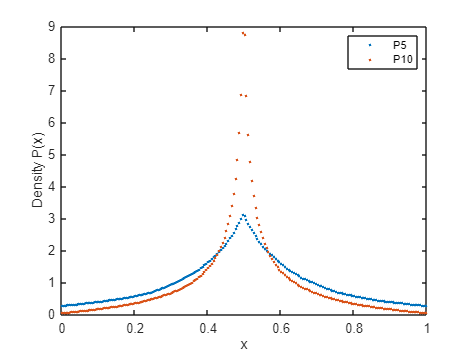


 plot(x,y1,'.',LineWidth=2);
hold on; 
plot(x,y2,'.',LineWidth=2);
% plot(x,y3,'.',LineWidth=2);
% plot(x,y4,'.',LineWidth=2);
% plot(x,y5,'.',LineWidth=2);
%plot(x,avg)
xlabel('x');
ylabel('Density P(x)');
%title('Segment Density: Average');
legend('P5', 'P10');
hold off; 